# Writing an ODE function for a Second-Order ODE

Do not edit. This code solves the ODE and visualizes the numerical and analytical solution.

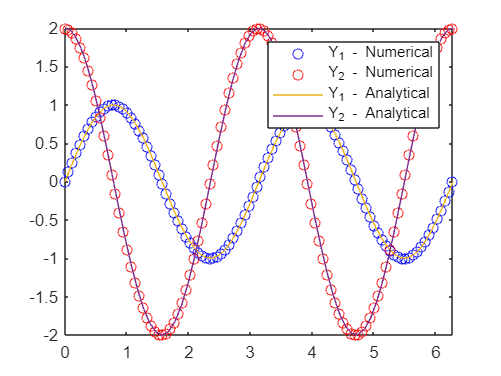

% Solve the system of ODEs
tRange = [0 2*pi];
Y0 = [0;2];
[tSol,YSol] = ode45(@secondOrder,tRange,Y0);

% Visualize analytical solution
xvals =  linspace(0,2*pi);
Y1An = sin(2*xvals);
Y2An = 2*cos(2*xvals);
plot(xvals,Y1An,"bo")
hold on
plot(xvals,Y2An,"ro")
hold off

% Visualize numerical solution
Y1 = YSol(:,1);
Y2 = YSol(:,2);
hold on
plot(tSol,Y1,tSol,Y2)
hold off
xlim([0 2*pi])
legend("Y_1 - Numerical","Y_2 - Numerical","Y_1 - Analytical","Y_2 - Analytical")

## Task 1

Follow the steps below to re-write any second-order ODE as a system of first-order ODEs.

- If y appears in the ODE, re-write it as Y1. 

-  If dydt appears in the ODE, re-write it as Y2. 

-  Re-write the second derivative as dY2dt.

 Your two first-order ODEs should only contain variables Y1 and Y2

Task

The local function `secondOrder` is located at the bottom of the script. 

Complete the expressions for `dY1dt` and `dY2dt` so that `secondOrder` represents the following ODE:

d2y/dt2+4y=0

Store `dY1dt` and `dY2dt` in a column vector named `dYdt`.

function dYdt = secondOrder(t,Y)

% Extract Y1, the first element of Y.
Y1 = Y(1);

% Extract Y2, the second element of Y.
Y2 = Y(2);

% TODO - Complete expression for dY1dt.
dY1dt=Y2;

% TODO - Complete expression for dY2dt.
dY2dt=-4.*Y1;

% TODO - Create dYdt, column vector containing dY1dt, dY2dt.
dYdt=[dY1dt;dY2dt];

end